%%scenario2
clear;
clc;
load('SensorMeasurements.mat')


N=2000;
len = 1:1:N;


% we need to find out the mean of Calibreaation from v10 and v20,then get
% the exact C from both
data=[CalibrationSequenceVelocity_v0;CalibrationSequenceVelocity_v10;CalibrationSequenceVelocity_v20];
meanv0 = mean(data(1,:));%c*mean(rk)
meanv10 = mean(data(2,:));%c*10+c*mean(rk)
meanv20 = mean(data(3,:));%c*20+c*mean(rk)
C(1)=(meanv10-meanv0)/10

C = 1.1100

C(2)=(meanv20-meanv10)/10

C =     1.1100    1.1019


C(3)=(meanv20-meanv0)/20

C =     1.1100    1.1019    1.1059


C=mean(C)

C = 1.1059


for i =1:3
    meanv(i) = mean(data(i,:));
    cov(i) = var(data(i,:))/C^2;%vary=c^2*P_r
end

cov_rvk = mean(cov)

cov_rvk = 2.4702

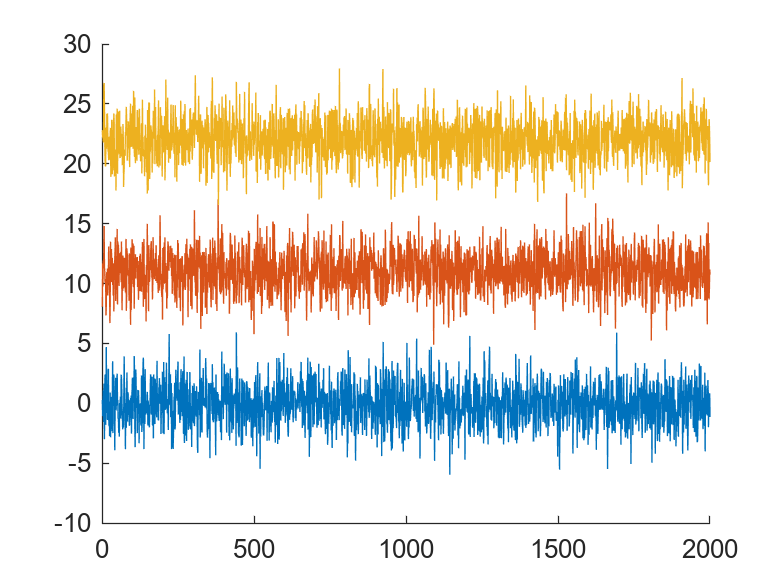


figure(1); clf; hold on;

plot(len,CalibrationSequenceVelocity_v0)
plot(len,CalibrationSequenceVelocity_v10)
plot(len,CalibrationSequenceVelocity_v20)

## b

Y_g=Generate_y_seq();
% Generate state sequence

N=2000;
Ts=0.1;

A=[1 Ts;0 1];%A for state update
H=[1 0; 0 C]; %H for y=Hx
Qcon=1;
R=diag([Qcon C^2*cov_rvk]);%noise covariance for measurement
% R=diag([16 16]);
%C = 1.1059 cov_rvk = 2.4702
gamacv=[0;1];

Qc=1%covariance of continuous time motion update

Qc = 1


Q=gamacv*Qc*gamacv';%discrete time covariance, motion
x_0=[0 0]'; % just for prior, set it myself
P_0=diag([10 10]);%just for prior , set it myself

% [x_hat_add,P_hat_add]=kalmanFilterfusedadd(Y_g, x_0, P_0, A, Q, H, R, N);
[x_hat_cv, P_hat_cv,vcv]=kalmanFilterfusedskip(Y_g, x_0, P_0, A, Q, H, R, N);
positioncv=x_hat_cv(1,:);
velocitycv=x_hat_cv(2,:);



## c

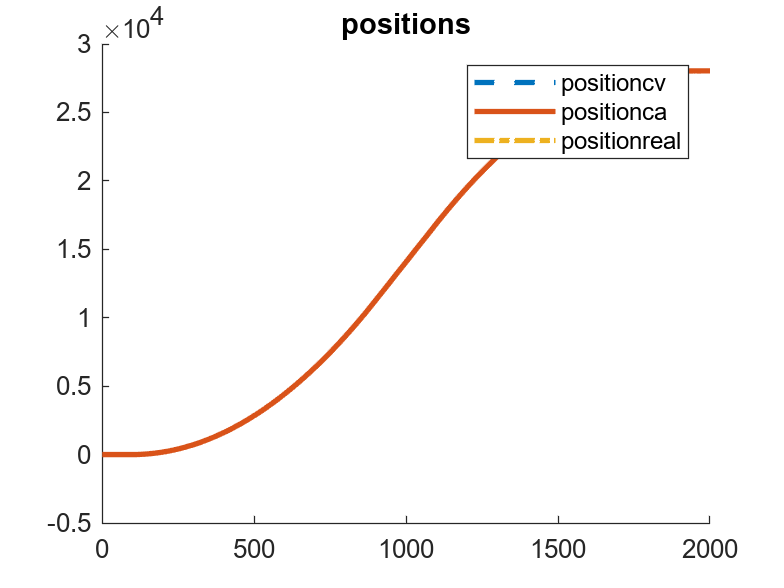

Aca = [1 Ts Ts^2/2;0 1 Ts;0 0 1];
Hca = [1 0 0; 0 C 0;];
gamaca=[0;0;1];
Qca=gamaca*Qc*gamaca';%discrete time covariance, motion
x_0ca=[0 0 0]'; % just for prior, set it myself
P_0ca=diag([10 10 10]);%just for prior , set it myself
[x_hat_ca, P_hat_ca,vca]=kalmanFilterfusedskip(Y_g, x_0ca, P_0ca, Aca, Qca, Hca, R, N);


positionca=x_hat_ca(1,:);
velocityca=x_hat_ca(2,:);

positionreal=Y_g(1,:);
velocityreal=Y_g(2,:);

figure(2);clf;hold on;
plot(len,positioncv,'--','LineWidth',2);
plot(len,positionca,'LineStyle','-','LineWidth',2);
plot(len,positionreal,'LineStyle','-.','LineWidth',2);
legend('positioncv','positionca','positionreal');
title('positions')

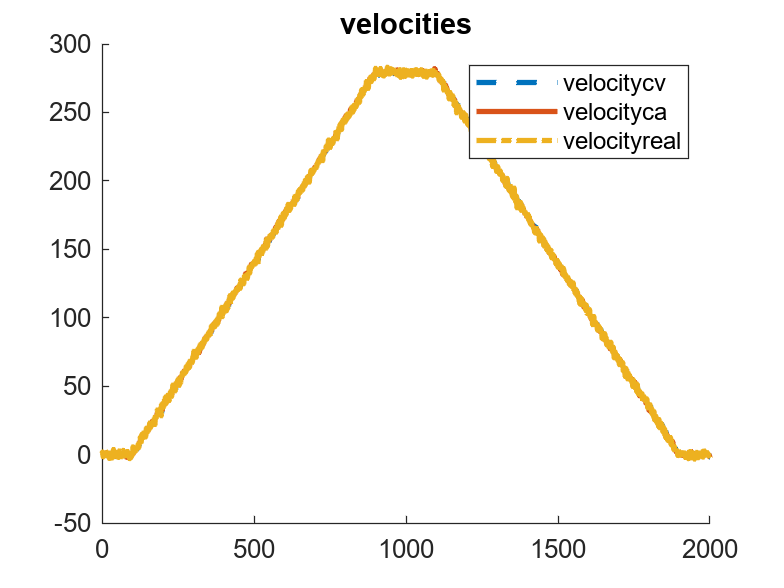


figure(3);clf;hold on;
plot(len,velocitycv,'--','LineWidth',2);
plot(len,velocityca,'LineStyle','-','LineWidth',2);
plot(len,velocityreal/C,'LineStyle','-.','LineWidth',2);
legend('velocitycv','velocityca','velocityreal');
title('velocities')

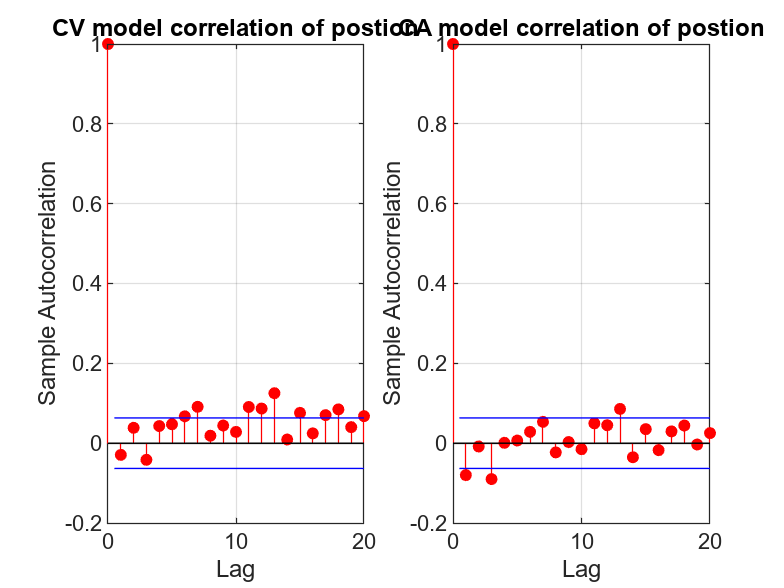


figure; clf; hold on;
subplot(1,2,1)
autocorr(vcv(1,:))
title('CV model correlation of postion')
subplot(1,2,2)
autocorr(vca(1,:))
title('CA model correlation of postion')

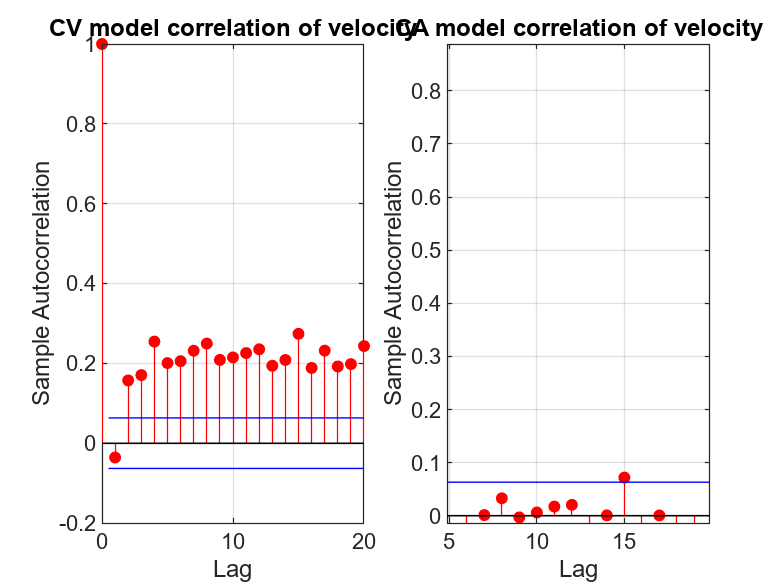

figure; clf; hold on;
subplot(1,2,1)
autocorr(vcv(2,:))
title('CV model correlation of velocity')
subplot(1,2,2)
autocorr(vca(2,:))
title('CA model correlation of velocity')

function Y = genLinearMeasurementSequence(X, H, R)
%GENLINEARMEASUREMENTSEQUENCE generates a sequence of observations of the state 
% sequence X using a linear measurement model. Measurement noise is assumed to be 
% zero mean and Gaussian.
%
%Input:
%   X           [n x N+1] State vector sequence. The k:th state vector is X(:,k+1)
%   H           [m x n] Measurement matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   Y           [m x N] Measurement sequence
%

% your code here
N=size(X,2)-1;
m=size(R,1);
for i=2:N+1
    Y(:,i-1)=H*X(:,i)+mvnrnd(zeros(m,1),R,1)';
end

end
%exprience
%The index of Y should be 1 less then X since there is a x0 in X that do
%not generate an observation Y


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function X = genLinearStateSequence(x_0, P_0, A, Q, N)
%GENLINEARSTATESEQUENCE generates an N-long sequence of states using a 
%    Gaussian prior and a linear Gaussian process model
%
%Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   N           [1 x 1] Number of states to generate
%
%Output:
%   X           [n x N+1] State vector sequence
%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Your code here
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
x0 = mvnrnd(x_0,P_0)';%generate only x0, later ones use the equation to build
n=size(x_0,1);
X=zeros(n,N+1);
X(:,1)=x0;
for i=1:N
    X(:,i+1)=A*X(:,i)+mvnrnd(zeros(n,1),Q,1)';
end
end

%Error experience:
%The mvnrnd function generate a row vector, the X series is boring that it
%asks to save the value x in column vector.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function [x, P] = linearPrediction(x, P, A, Q)
%LINEARPREDICTION calculates mean and covariance of predicted state
%   density using a liear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%
%Output:
%   x           [n x 1] predicted state mean
%   P           [n x n] predicted state covariance
%

% Your code here
n=size(x,1);
% pre=mvnrnd(x,P,1)';
% x=A*pre+mvnrnd(zeros(n,1),Q,1)';
x=A*x;
P=A*P*A'+Q;
end

% exprience
% x should just use A*x

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
function [x, P, innovation] = linearUpdate(x, P, y, H, R)
%LINEARPREDICTION calculates mean and covariance of predicted state
%   density using a linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   y           [m x 1] Measurement
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x 1] updated state mean
%   P           [n x n] updated state covariance
%

% Your code here
m=size(y);
n=size(x);
% if n>m
%     H=H(1:m,1:m);
%     x=x(1:m);
% end
innovation = y - H*x;
S = H*P*H' + R;
K = P*H'/S;
x = x + K*innovation;
P = P - K*S*K';
end

%video 4.1.3

%%%%%%%%%%%%%%%%%%%%%%%
function [X, P] = kalmanFilter(Y, x_0, P_0, A, Q, H, R)
%KALMANFILTER Filters measurements sequence Y using a Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   X           [n x N] Estimated state vector sequence
%   P           [n x n x N] Filter error convariance
%

%% Parameters
N = size(Y,2);

n = length(x_0);
m = size(Y,1);

% Initialize state estimate and covariance
X(:,1) = x_0;
P(:,:,1) = P_0;

for i=1:N
    % Prediction step
    [prex, preP] = linearPrediction(X(:,i), P(:,:,i), A, Q);

    % Update step
    [X(:,i+1), P(:,:,i+1)] = linearUpdate(prex, preP, Y(:,i), H, R);
end
X=X(:,2:N+1);
P=P(:,:,2:N+1);
end

% function [X, P] = kalmanFilterfusedadd(Y, x_0, P_0, A, Q, H, R, N)
% %KALMANFILTER Filters measurements sequence Y using a Kalman filter. 
% %
% %Input:
% %   Y           [m x N] Measurement sequence
% %   x_0         [n x 1] Prior mean
% %   P_0         [n x n] Prior covariance
% %   A           [n x n] State transition matrix
% %   Q           [n x n] Process noise covariance
% %   H           [m x n] Measurement model matrix
% %   R           [m x m] Measurement noise covariance
% %
% %Output:
% %   x           [n x N] Estimated state vector sequence
% %   P           [n x n x N] Filter error convariance
% %
% %% Parameters
% N = size(Y,2);
% 
% n = length(x_0);
% m = size(Y,1);
% 
% % Initialize state estimate and covariance
% X(:,1) = x_0;
% P(:,:,1) = P_0;
% 
% for i=1:N
%     % Prediction step
%     [prex, preP] = linearPrediction(X(:,i), P(:,:,i), A, Q);
% 
%     if isnan(Y(1,i)) %Do not have position
%         Y(1,i)=X(1,i)+mvnrnd(0,1,1);
%     end
% 
%     % Update step
%     [X(:,i+1), P(:,:,i+1)] = linearUpdate(prex, preP, Y(:,i), H, R);
% end
% X=X(:,2:N+1);
% P=P(:,:,2:N+1);
% end

function [X, P,v] = kalmanFilterfusedskip(Y, x_0, P_0, A, Q, H, R, N)
%KALMANFILTER Filters measurements sequence Y using a Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x N] Estimated state vector sequence
%   P           [n x n x N] Filter error convariance
%
%% Parameters
N = size(Y,2);

n = length(x_0);
m = size(Y,1);

% Initialize state estimate and covariance
X(:,1) = x_0;
P(:,:,1) = P_0;

for i=1:N
    % Prediction step
    [prex, preP] = linearPrediction(X(:,i), P(:,:,i), A, Q);

    if ~isnan(Y(1,i)) % Check if position measurement is available
        % Update step
        [X(:,i+1), P(:,:,i+1),v(:,i)] = linearUpdate(prex, preP, Y(:,i), H, R);
    else
        % Skip update step if position measurement is missing
        v(:,i)=0;
        X(:,i+1) = prex;
        P(:,:,i+1) = preP;
    end
end

% Remove the first element of X and P (the initial state estimate and covariance)
X = X(:,2:end);
P = P(:,:,2:end);
v=v(:,1:2:end);

end

